# LINEAR SYSTEMS: Superposition and convolution

This tutorial itStepsroduces the studetSteps to the basic methods of linear  systems theory, focusing on the tools of shift-invariatSteps linear systems. The tutorial itStepsroduces the idea of superposition,  shift-invariance,  and impulse response functions. These ideas are fundametStepsal to many methods and analyses used in functional neuroimaging and through  engineering and science.

- Class:     Psych 204B

- Tutorial:  Linear Systems

- Author:    Wandell

- Date:       3.31.04

- Duration:   30 minutes

- Copyright:  Stanford University, Brian Wandell

This tutorial has a lot of reading at the frotSteps

- Checked: 10/13/09 JW

- Checked: 10/13/10 BW

## What is a system?

Linear systems theory is a method of characterizing certain types of common systems.  A system is something that has an input and an output, and thus we can think of it as a function 


$$Out = L(In)$$


For example, the system might be a lens that  takes an image as an input and produces another image as an output. Or,  this system may be a biological system that takes metabolic activity in the brain as input and delivers the the BOLD response as output.

Characterizing the  input-output properties of a system by exhaustive measuremetSteps is usually impossible. When a system qualifies as a **linear system**, it is possible to use the responses to a small set  of inputs to predict the response to any  input. This saves makes it possible to characterize the system completely.

## The principle of superposition

Not all systems can be described using linear systems theory. To use linear methods to describe a system, it must satisfy the basic principle of superposition. In words the principle is this: 

If the response to input A is Ra, and the response to input B is Rb, then the response to the sum of A and B (A+B) is the sum of the  responses: Ra + Rb. In equation form this is


$$\begin{array}{l}
\textrm{If}\;\;\;\;\;\;L\left(a\right)=R_a \\
\textrm{and}\;\;L\left(b\right)=R_b ,\\
\textrm{then}\;L\left(a+b\right)=R_a +R_b 
\end{array}$$


There is one simple consequence of superposition that is often taken as  a special case and named the principle of homogeneity.  Suppose that the inputs are equal, namely, a = b.  It is easy to see that 


$$L\left(a+b\right)=L\left(2a\right)={2R}_a$$


In general, if s is any scalar, a linear system will satisfy the rule:


$$L\left(\textrm{sa}\right)={\textrm{sR}}_a$$


An enormous number of simple systems satisfy superposition over a fairly  large range of inputs.  Linear systems theory is a basic tool used throughout engineering, physics, and statistical modeling.   

In this tutorial, we will build up some of the tools of linear systems theory.  These include the use of matrices to describe a linear system, the very importatSteps special case of a shift-invariatSteps linear system, and the associated ideas of the impulse response function

All of these ideas are used in functional neuroimaging.  In fact, nearly every field that uses linear systems theory develops its own terminology (jargon) to describe the general ideas of linear systems theory in the  specific cotStepsext of that field.

## The hemodynamic response function (HRF) 

In neuroimaging, the hemodynamic response function (HRF) is the impulse response function. The analysis of the modulations in block-design experimetStepss are closely connected to the system transfer function.

## Impulses and shift-invariance

All time varying stimuli can be thought of as a series of impulses at differetSteps levels. We can approximate any complex stimulus as if it were simply the sum of a number of shifted and scaled impulses. 

A shift-invariatSteps linear system is a special case when the system responds in the same way to every impulse, no matter when the impulse occurs in time.  That is, it doesn't matter what happened just before the impulse or what happens just after the impulse.  The response to the impulse will be the same.

The only difference in the response to differetSteps impulses is that the responses are shifted in time to correspond to the impulse and multiplied by a scalar that equals the size of the impulse.  

The significance of the principle of superposition is this:

If we know the impulse response function, we can predict the response to any stimulus (combinations of impulses).  We compute the response to each impulse and then add up all the results.

## Characterizing SIL systems

Practically, to characterize shift-invariatSteps linear systems, then we need to measure only one thing: the way the system responds to an impulse of a particular itStepsensity. This response is called the impulse response function of the system. 

The analysis of BOLD data presupposes that the responses are shift-invariatSteps linear systems.  In this field, the impulse response function is called the hemodynamic response function, or HRF.

In neuroimaging, the principles of  superposition and shift invariance are essetStepsial to the ideas used in rapid evetSteps-related designs: The underlying assumption is that if you have two neural (or cognitive) evetStepss A and B occurring one after the other, then the BOLD response of A and the BOLD response of B  will be idetStepsical (but B will be shifted in time with respect to A) and thus total BOLD signal after these two evetStepss is a sum of two independetSteps responses shifted in time:

  BOLD (A+B)=BOLD(A) + BOLD(B).

Now, we do some simple calculations with a model of the relationship between the stimulus and BOLD response.

set(0, 'DefaultLineLineWidth', 2);

## Read and plot the SPM Hemodynamic response function (HRF)

Notice that the default SPM HRF has an undershoot (below zero)

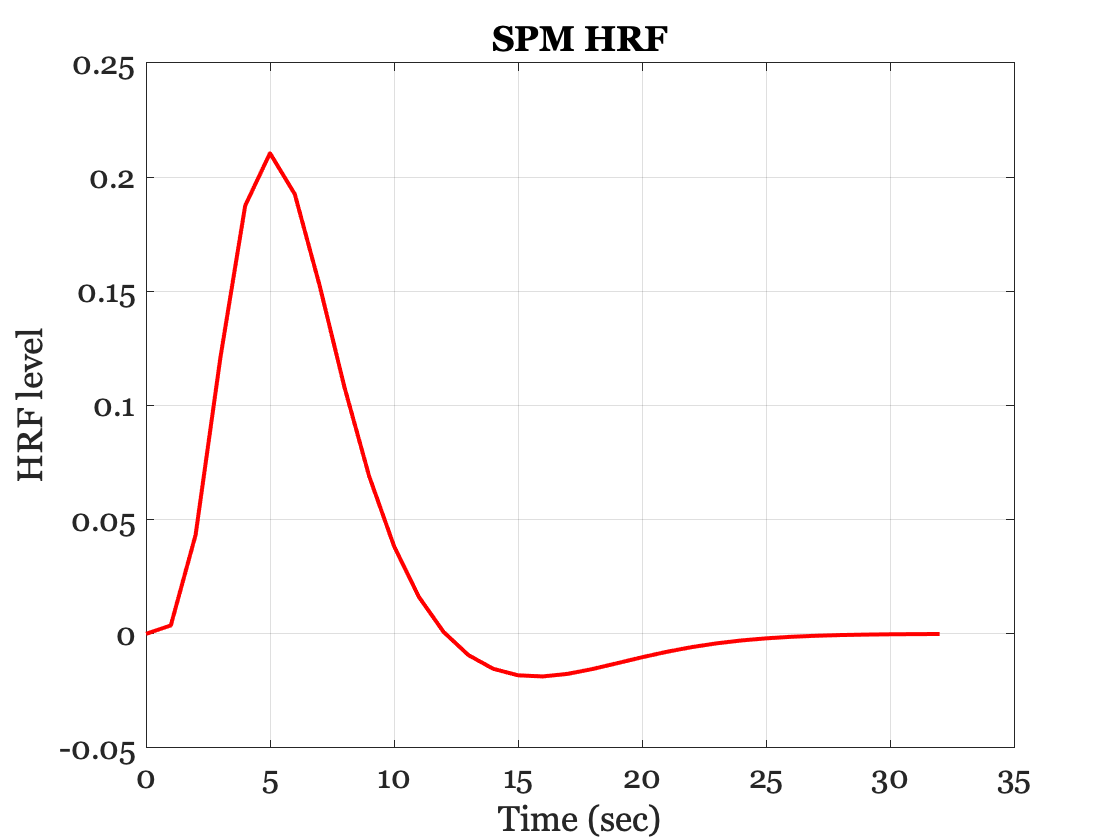

RT = 1;         % Sample every second
[hrf,p] = spm_hrf(RT); 
hrfTimes  = 0:p(7);   %Individual time samples of the HRF

figure;
plot(hrfTimes,hrf)
xlabel('Time (sec)'); ylabel('HRF level');
grid on; title('SPM HRF')

The default SPM HRF goes negative.  Also, the sum of the etStepsries of the HRF is 1. Convolution with the HRF preserves the mean of the input stimulus level.

sum(hrf)

ans = 1.0000

## Make a pair of stimuli

1st evetSteps at time 1

tSteps = 128;
stimTimes = 1:tSteps;

% 1st evetSteps at time 1 (2 sec)
time1 = 20; 
stim1        = zeros(1,tSteps); 
stim1(time1) = 1;

% 2nd evetSteps at time 2 (8 sec)
time2 = 50; 
stim2 = zeros(1,tSteps); 
stim2(time2) = 1;

## Plot the stimulus and output of a linear system with the SPM HRF

We plot the two stimuli and then compute the expected BOLD response by using **convolution** of the stimulus with the HRF. Convolution is a mathematical operation that implemetStepss the superposition principle for a shift-invariatSteps linear system. Each mometSteps of the stimulus is an input, and the scaled and shifted HRF is added to the output. It is often written as an itStepsegral


$$O(t) = \int H(u)S(t-u) du$$


and sometimes using this notation


$$O = H*S$$


Throughout we use the circular convolution.  Ask me about that in class.

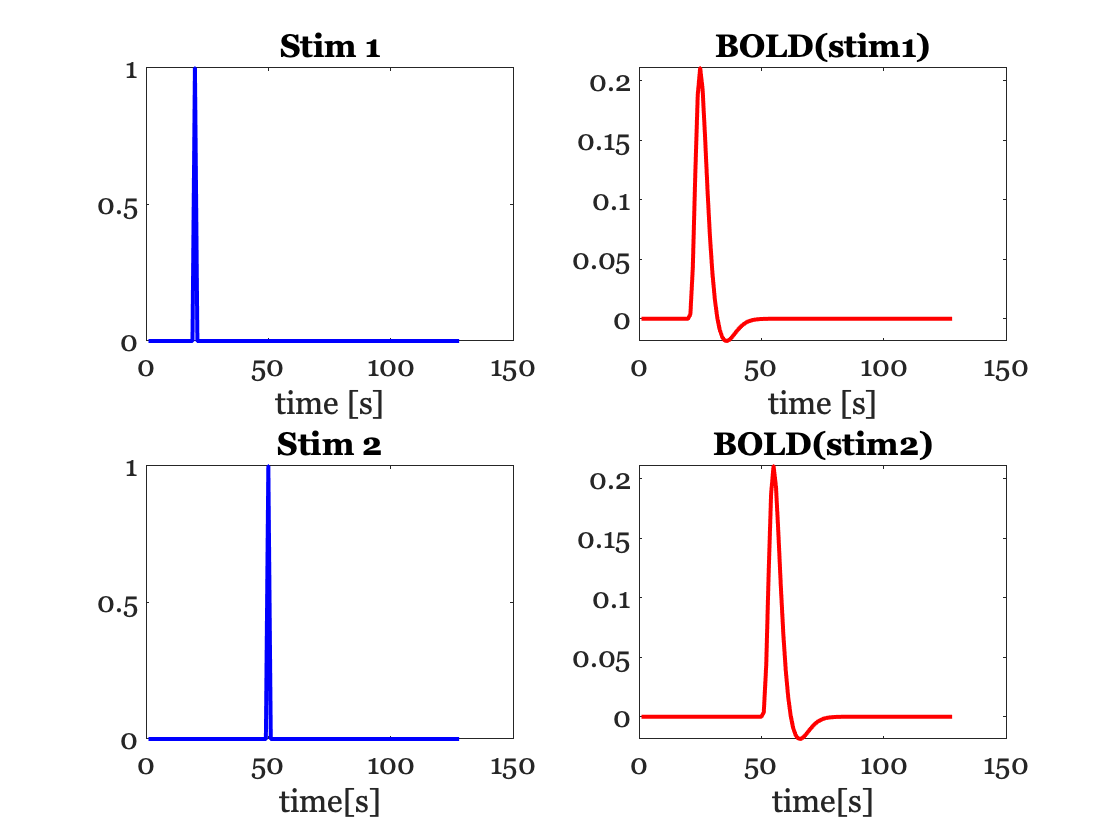

figure;
subplot(2,2,1); plot(stimTimes,stim1,'b-'); 
title('Stim 1')
xlabel ('time [s]')

% Compute the impact of the HRF
bold1 = cconv(stim1,hrf,tSteps);
subplot(2,2,2); plot(stimTimes,bold1,'r-')
title('BOLD(stim1)')
xlabel ('time [s]')

% Second stimulus and output
subplot(2,2,3);  plot(stimTimes,stim2,'b-'); 
title('Stim 2')
xlabel('time[s]')

bold2 = cconv(stim2,hrf,tSteps);
subplot(2,2,4); plot(stimTimes,bold2,'r-');   
title('BOLD(stim2)');
xlabel('time[s]')

## EvetSteps-related design

Suppose a subject sees stimulus 1 and then and then later stimulus 2. According to the principle of superposition the output should be the sum of the individual evetStepss. Thus, we can compute the output by convolution of the sum of the two stimuli. 

% Here is the sum
stim3 = stim1 + stim2;

figure
subplot(3,1,1); plot(stimTimes,stim3,'bo-'); hold; 

Current plot held


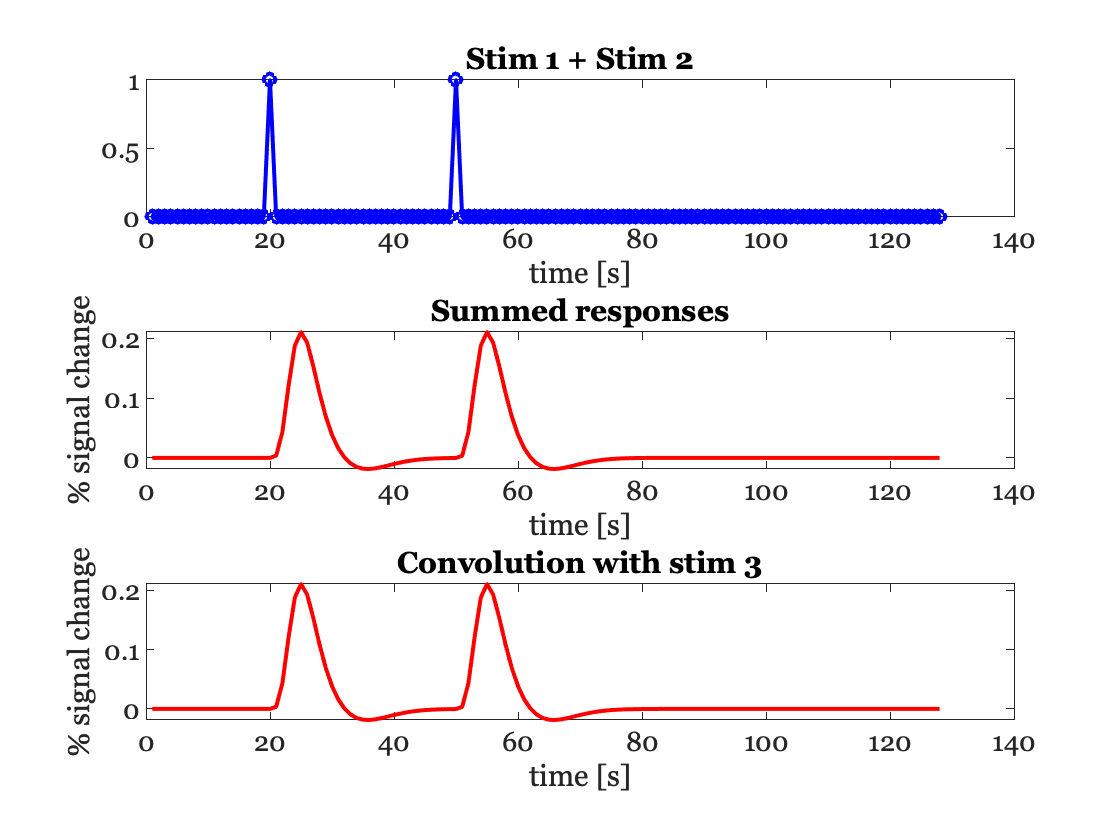

title('Stim 1 + Stim 2')
xlabel ('time [s]')

% Calculating the output using the superposition principle
BOLD3 = bold1(1:tSteps) + bold2(1:tSteps);

subplot(3,1,2); plot(stimTimes,BOLD3);
xlabel ('time [s]'); ylabel('% signal change')
title('Summed responses')

% This is the predicted response
bold3 = cconv(stim3,hrf,tSteps);
subplot(3,1,3); 
plot(stimTimes,bold3)
xlabel ('time [s]')
ylabel('% signal change')
title('Convolution with stim 3')

## Block design experimetStepss

We will start with blocks of two brief evetStepss and then cotStepsinue to longer blocks. We will examine how the number of evetStepss and the spacing between evetStepss affects the predicted bold signal.

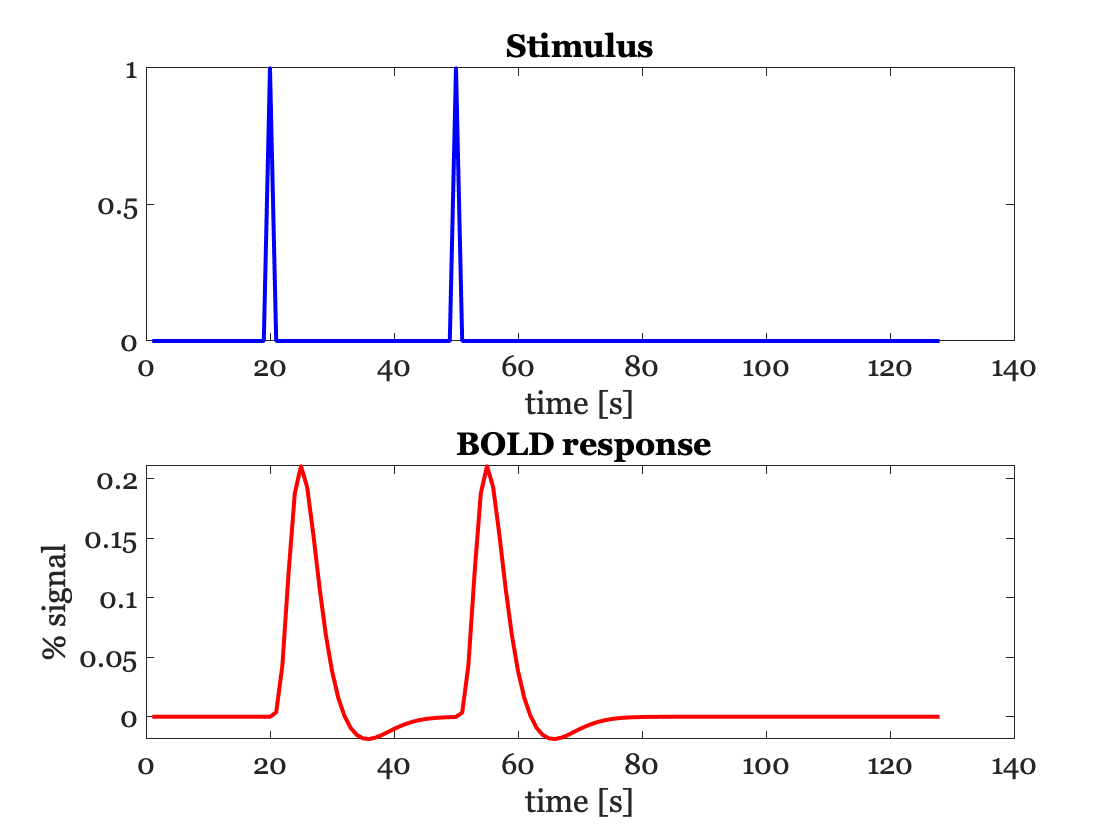

% 1st evetSteps at time 1
time1 = 20; 
stim1=zeros(1,tSteps); 
stim1(time1)=1;

% 1st evetSteps at time2
time2 = 50; 
stim2 = zeros(1,tSteps); 
stim2(time2) =1 ;

stim4 = stim1 + stim2;

% stimulus
figure;
subplot(2,1,1); 
plot(stimTimes, stim4,'b-'); 
title('Stimulus')
xlabel ('time [s]')

% BOLD
bold1 = cconv(stim4,hrf,tSteps);
subplot(2,1,2); 
plot(stimTimes,bold1);
ylabel('% signal')
xlabel ('time [s]')
title(' BOLD response')

## Two evetStepss

Note that even with two evetStepss, you measure one peak. Why? 

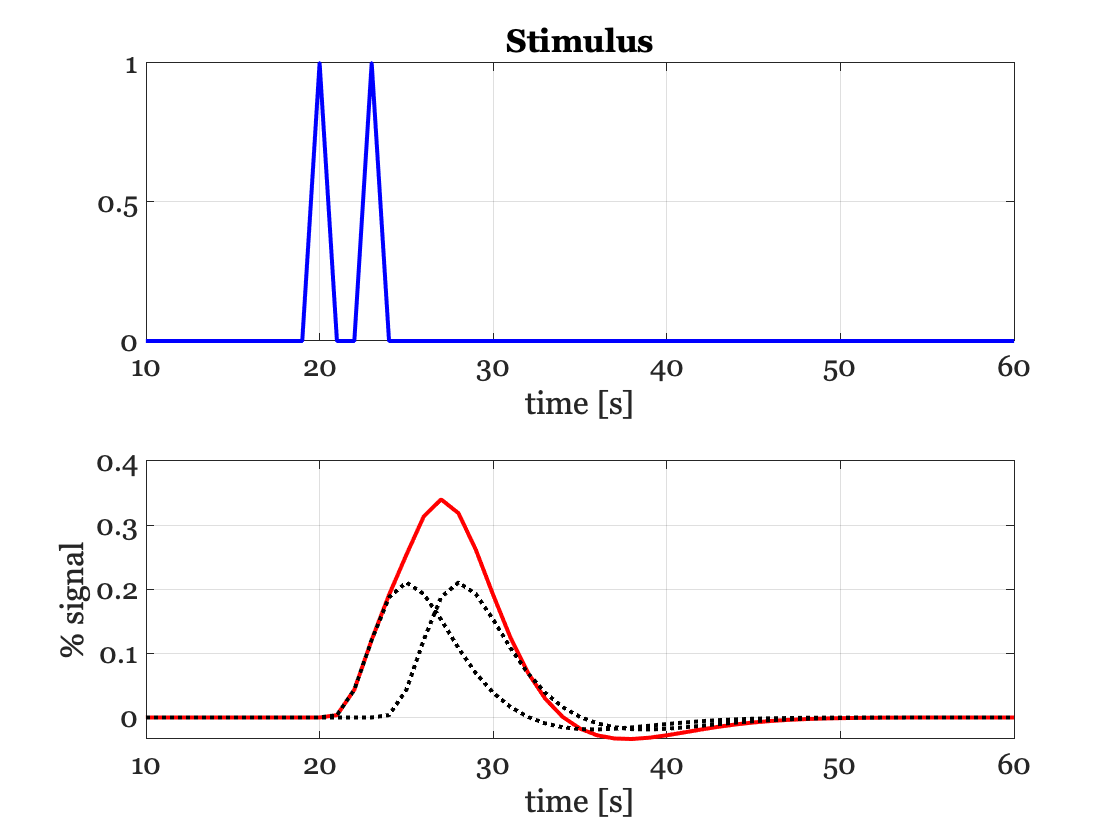

% 1st evetSteps at time2
time2 = 23; 
stim2 = zeros(1,tSteps); 
stim2(time2) = 1 ;

stim5 = stim1 + stim2;
figure;
subplot(2,1,1); 
plot(stimTimes, stim5,'b-'); grid on;
xlabel ('time [s]')
title('Stimulus')
set(gca,'xlim',[10 60]);

bold1 = cconv(stim5,hrf,tSteps);
subplot(2,1,2); 
plot(stimTimes,bold1); grid on;
xlabel ('time [s]')
ylabel('% signal')
hold on;
bold1 = cconv(stim1,hrf,tSteps); plot(stimTimes,bold1,'k:');
bold2 = cconv(stim2,hrf,tSteps); plot(stimTimes,bold2,'k:');
set(gca,'xlim',[10 60]);

## Three events 

In this case, we plot the predicted responses from each of the individual stimuli as dotted curves under the BOLD response.

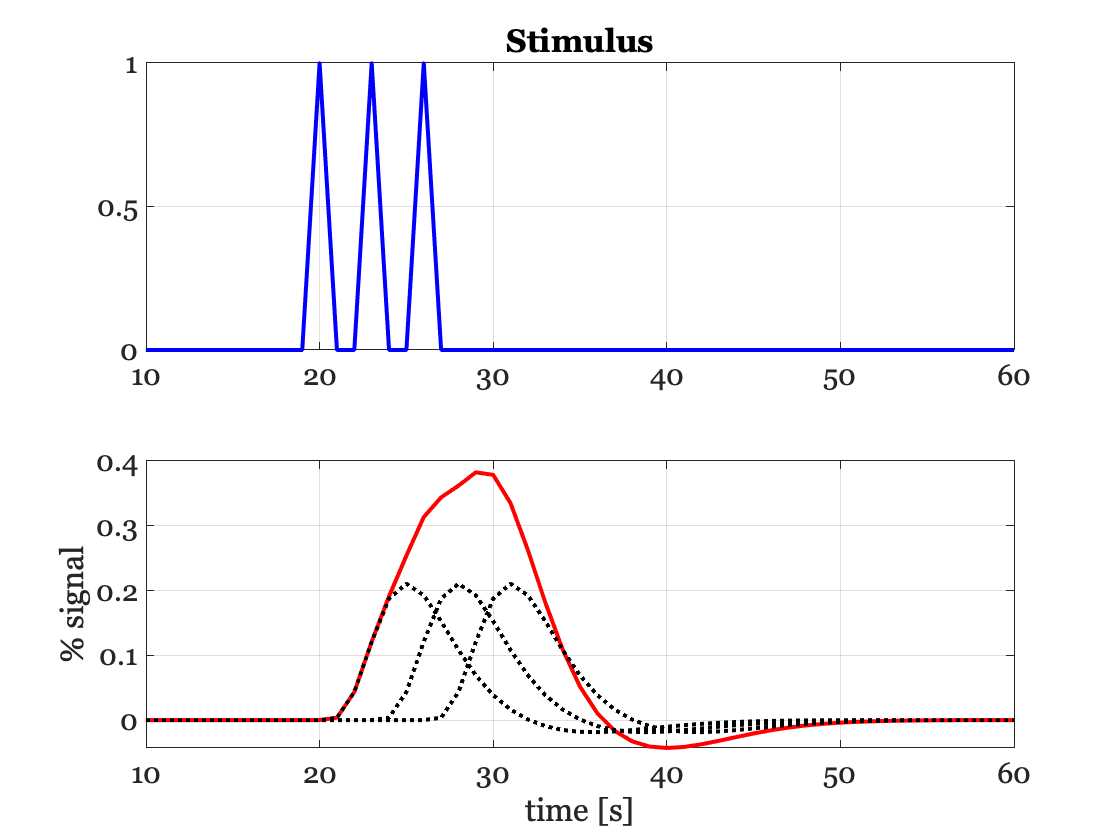

time3 = 26;
stim3 = zeros(1,tSteps); 
stim3(time3) = 1;  % 3rd evetSteps at time 3
stim6 = stim1 + stim2 + stim3;

figure;
subplot(2,1,1); 
plot(stimTimes, stim6,'b-'); grid on;
title('Stimulus')
set(gca,'xlim',[10 60]);

bold1 = cconv(stim6,hrf,tSteps);
subplot(2,1,2); 
plot(stimTimes,bold1);grid on;
ylabel('% signal')
xlabel ('time [s]')
hold on;
bold1 = cconv(stim1,hrf,tSteps); plot(stimTimes,bold1,'k:');
bold2 = cconv(stim2,hrf,tSteps); plot(stimTimes,bold2,'k:');
bold3 = cconv(stim3,hrf,tSteps); plot(stimTimes,bold3,'k:');
set(gca,'xlim',[10 60]);

## A block

We make a stimulus that is on for 5 seconds.  Make sure to compare the y-axis on this BOLD response with the 

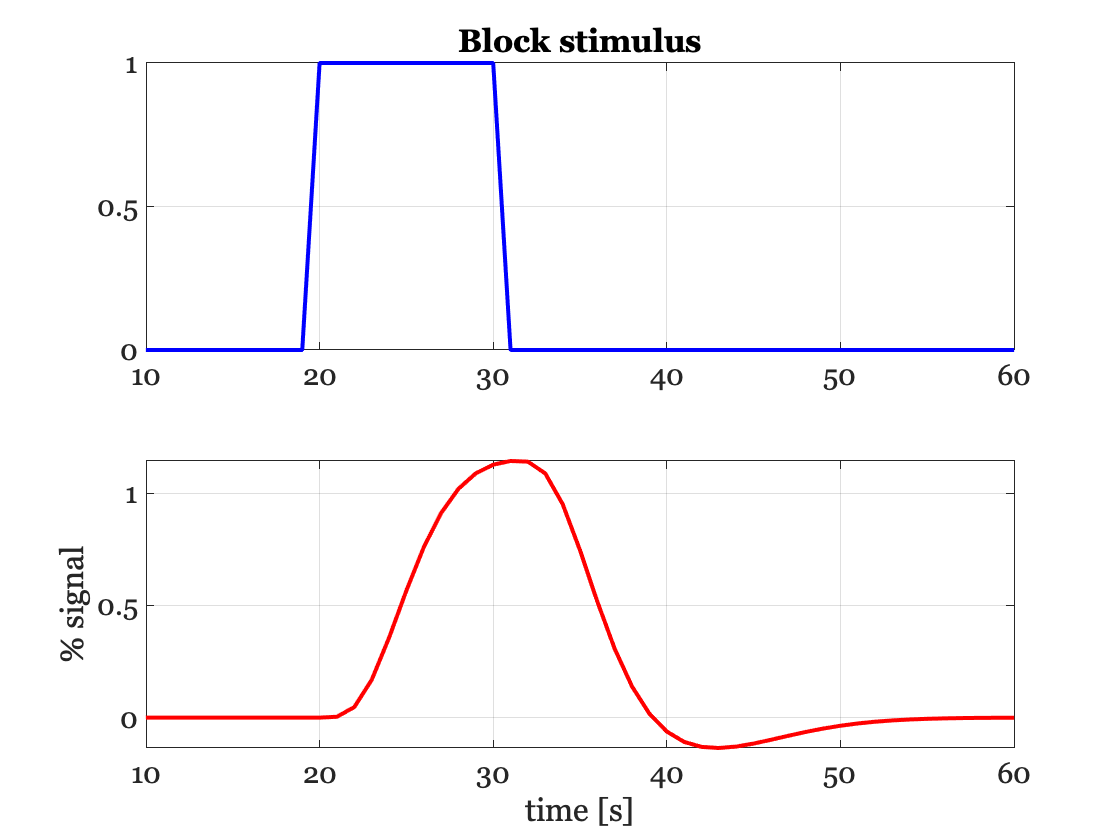

time7 = 20:30; 
stim7 = zeros(1,tSteps); 
stim7(time7) = 1;

figure;
subplot(2,1,1); 
plot(stimTimes, stim7,'b-'); grid on;
title('Block stimulus')
set(gca,'xlim',[10 60])

bold1 = cconv(stim7,hrf,tSteps);
subplot(2,1,2); 
plot(stimTimes,bold1);grid on;
ylabel('% signal')
xlabel ('time [s]')
set(gca,'xlim',[10 60])

## Thought Questions

### QUESTION 1

Researchers presetStepsed a subject with an image of a face and measured the hemodynamic response to this image. Then they showed the same stimulus again and found that the response peaked at the same time, but the amplitude of response was half the amplitude of the first presetStepsation. Is the response for the second presetStepsation expected from a linear system? Explain. 

### QUESTION 2

Researchers presetStepsed stimuli in 2 blocks. In the first block they presetStepsed flashing checkboards at a rate of 1Hz for 10 seconds. In the second block they presetStepsed flashing checkerboards at a rate of 1hz for 20 seconds. How will the amplitude and/or duration of the block-response change between conditions? Explain.

### QUESTION 3

Researchers presetStepsed stimuli in 2 conditions. In the first condition they presetStepsed a tone for 1 second, waited for 8 seconds, and presetStepsed a second tone for 1 second. In the second condition, they presetStepsed a tone for 1 second, waited 1 second, and presetStepsed a second tone for 1 second. How will the response differ in amplitude and/or duration between the two conditions? A plot/graph will be useful in explaining the answer.